## MathTools HW 2

## 2024-10-2

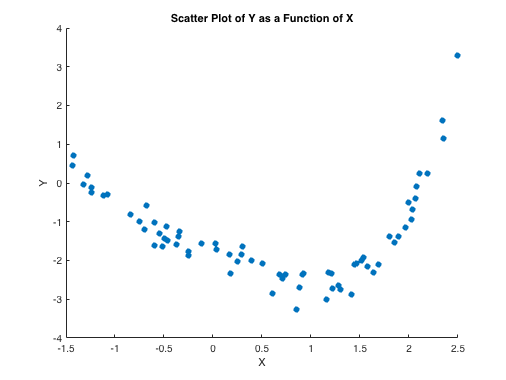

clear all; clc; close all;

addpath('hw2-files/');
load('regress1.mat'); 

figure;
scatter(x, y, 'filled');
xlabel('X');
ylabel('Y');
title('Scatter Plot of Y as a Function of X');

orders = 0:5; numOrder = length(orders); 

%Empty hodler
squaredErrors = zeros(1,numOrder); 
coeffs = cell(1, numOrder);
fitted_Y = cell(1, numOrder);

for i = 1:numOrder
    order = orders(i);
    vandermonde = zeros(length(x), order + 1);

    for j = 0:order
        vandermonde(:,j+1) = x.^j;
    end %for j

    [U, S, V] = svd(vandermonde);
    coeffs{i} = V * (S \ (U' * y));

    fitted_Y{i} = vandermonde * coeffs{i};

    squaredErrors(i) = sum((y - fitted_Y{i}).^2);
    
end %for i

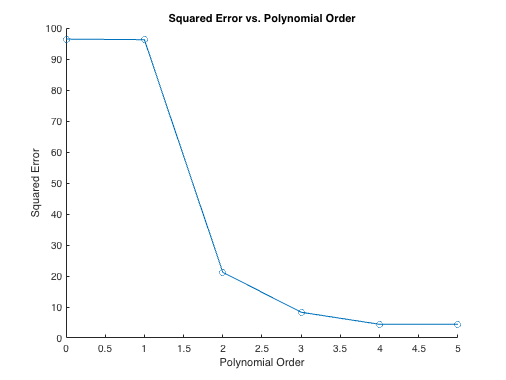

%Plotting the squared error as a function of the order of the polynomial
figure; hold on; 
plot(orders, squaredErrors, '-o');
xlabel('Polynomial Order');
ylabel('Squared Error');
title('Squared Error vs. Polynomial Order');

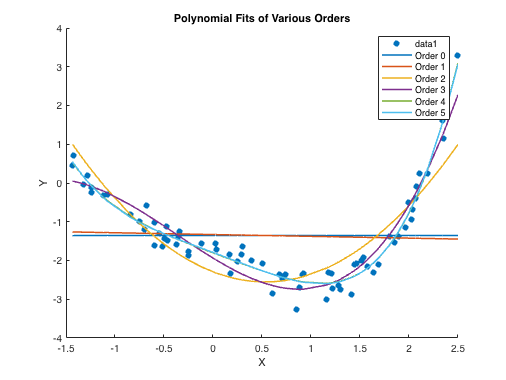

%Plotting the data and the polynomial fits
figure; hold on;
scatter(x, y, 'filled');

plotcolors = lines(numOrder); %for plotting use

for p = 1:numOrder
    plot(x, fitted_Y{p},'DisplayName', sprintf('Order %d', orders(p)), ...
        'Color', plotcolors(p, :), 'LineWidth', 1.5); 
end %for p

xlabel('X');
ylabel('Y');
title('Polynomial Fits of Various Orders');
legend('show');
hold off;

%Get the best fit
[MinError, orderIndex] = min(squaredErrors); 
bestFittingOrder = orders(orderIndex);
fprintf('The best polynomial fit is of order %d, with a squared error of %.4f\n', orderIndex-1, MinError);

The best polynomial fit is of order 5, with a squared error of 4.4146


Explanation for order 5 being the best fit it's because that oder bring the smallest squared error. 